# Examples 3.15 and 3.17: Covariance, Correlation, and Uncertainty Reduction in Gibbs Reactor

Note: this script reproduces Examples 3.15 (Section 3.7.2) and 3.17 (Section 3.8.3) of **Statistics for Chemical Engineers**: statistics of pressure, conversion, and flows of the Gibbs reactor. Victor Z UW-Madison, 2020 covariance and correlation matrix for gibbs reactor

clc; clear all; close all hidden;
format bank;

## Data

data order (pressure, conversion, flow co, flow h2, flow ch3oh)

load('./Data/gibbs_covariance.dat')
data=gibbs_covariance;

% perturb data with noise
rng(1); % For reproducibility 
data(:,1)=data(:,1)+normrnd(0,10,250,1);
data(:,2)=data(:,2)+normrnd(0,0.1,250,1);
data(:,3)=data(:,3)+normrnd(0,10,250,1);
data(:,4)=data(:,4)+normrnd(0,10,250,1);
data(:,5)=data(:,5)+normrnd(0,10,250,1);

## Mean, variance, covariance, and correlation (Example 3.15)

get mean

m=mean(data)'

m =         147.87
          0.69
         31.39
        461.95
         69.24



% get variance
v=var(data)'

v =         776.94
          0.02
        163.81
        338.35
        161.70



% get std dev
s= sqrt(v)

s =          27.87
          0.12
         12.80
         18.39
         12.72



% get covariance matrix
C=cov(data)

C =         776.94          1.83       -195.91       -396.57        181.45
          1.83          0.02         -0.54         -1.11          0.40
       -195.91         -0.54        163.81        117.59        -58.17
       -396.57         -1.11        117.59        338.35       -116.12
        181.45          0.40        -58.17       -116.12        161.70



% get correlation matrix
R=corrcov(C)

R =           1.00          0.53         -0.55         -0.77          0.51
          0.53          1.00         -0.34         -0.49          0.25
         -0.55         -0.34          1.00          0.50         -0.36
         -0.77         -0.49          0.50          1.00         -0.50
          0.51          0.25         -0.36         -0.50          1.00



% get eigenvalues of covariance matrix
lambda=eigs(C)

lambda =        1120.38
        116.63
        104.72
         99.08
          0.01


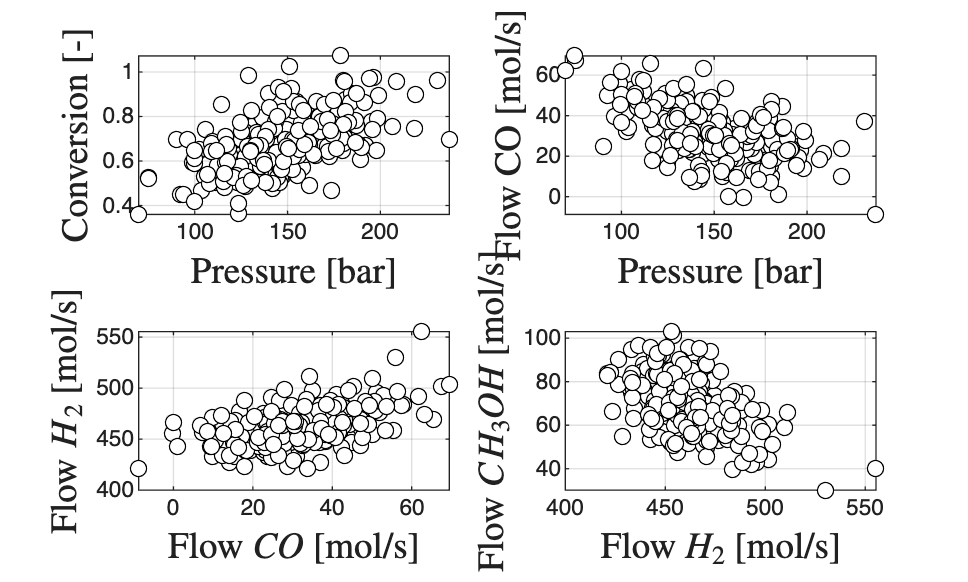


figure(1)
subplot(2,2,1)
plot(data(:,1),data(:,2),'blacko','MarkerFacecolor','w')
xlabel('\textrm{Pressure [bar]}','Interpreter','latex','FontSize',14)
ylabel('\textrm{Conversion [-]}','Interpreter','latex','FontSize',14)
grid on
subplot(2,2,2)
plot(data(:,1),data(:,3),'blacko','MarkerFacecolor','w')
xlabel('\textrm{Pressure [bar]}','Interpreter','latex','FontSize',14)
ylabel('\textrm{Flow CO [mol/s]}','Interpreter','latex','FontSize',14)
grid on
subplot(2,2,3)
plot(data(:,3),data(:,4),'blacko','MarkerFacecolor','w')
ylabel('\textrm{Flow $H{}_2$ [mol/s]}','Interpreter','latex','FontSize',14)
xlabel('\textrm{Flow $CO$ [mol/s]}','Interpreter','latex','FontSize',14)
grid on
subplot(2,2,4)
plot(data(:,4),data(:,5),'blacko','MarkerFacecolor','w')
ylabel('\textrm{Flow $CH_3OH$ [mol/s]}','Interpreter','latex','FontSize',14)
xlabel('\textrm{Flow $H_2$ [mol/s]}','Interpreter','latex','FontSize',14)
grid on
print -depsc ch3_correlation_gibbs.eps

## Scaled variables

re-scale variables

% get mean
m=mean(data)'

m =         147.87
          0.69
         31.39
        461.95
         69.24



% get variance
v=var(data)'

v =         776.94
          0.02
        163.81
        338.35
        161.70



% get std dev
s= sqrt(v)

s =          27.87
          0.12
         12.80
         18.39
         12.72



% scale 
for i=1:5
   data(:,i)=(data(:,i)-m(i))/s(i); 
end

% get covariance matrix
CC=cov(data)

CC =           1.00          0.53         -0.55         -0.77          0.51
          0.53          1.00         -0.34         -0.49          0.25
         -0.55         -0.34          1.00          0.50         -0.36
         -0.77         -0.49          0.50          1.00         -0.50
          0.51          0.25         -0.36         -0.50          1.00



% get correlation matrix
R=corrcov(CC)

R =           1.00          0.53         -0.55         -0.77          0.51
          0.53          1.00         -0.34         -0.49          0.25
         -0.55         -0.34          1.00          0.50         -0.36
         -0.77         -0.49          0.50          1.00         -0.50
          0.51          0.25         -0.36         -0.50          1.00



% get eigenvalues of covariance matrix
lambda=eigs(CC)

lambda =           2.96
          0.75
          0.62
          0.45
          0.22


## compute conditional density

% reorder matrix 

Cr=C([2 1 3 4 5],[2 1 3 4 5])

Cr =           0.02          1.83         -0.54         -1.11          0.40
          1.83        776.94       -195.91       -396.57        181.45
         -0.54       -195.91        163.81        117.59        -58.17
         -1.11       -396.57        117.59        338.35       -116.12
          0.40        181.45        -58.17       -116.12        161.70


mr=m([2 1 3 4 5])

mr =           0.69
        147.87
         31.39
        461.95
         69.24



% compute quantities
Sig11=Cr(1,1)

Sig11 =           0.02

Sig22=Cr(2:5,2:5)

Sig22 =         776.94       -195.91       -396.57        181.45
       -195.91        163.81        117.59        -58.17
       -396.57        117.59        338.35       -116.12
        181.45        -58.17       -116.12        161.70


mu2=mr(2:5)

mu2 =         147.87
         31.39
        461.95
         69.24


mu1=mr(1)

mu1 =           0.69

Sig21=Cr(2:5,1)

Sig21 =           1.83
         -0.54
         -1.11
          0.40


Sig12=Sig21';
x2p=mr(2:5);

%XI|X2
mu1g2=mu1+Sig12*inv(Sig22)*(x2p-mu2)

mu1g2 =           0.69

Sig1g2=Sig11-Sig12*inv(Sig22)*Sig21

Sig1g2 =           0.01

## Note

As in the book, the variables are strongly related, and the data cloud concentrates around the sample means; knowing the other variables reduces the variance of the conversion without shifting its mean (Example 3.17).